# **P02: Señales Continuas**

**Integrantes:**

Contreras Avilés Citlali Anahí

Gallegos Ruiz Diana Abigail

Morgado Reséndiz Lisardo René

Ramírez Aniceto Lauro Alexis

Rojas Gómez Ian

**PROFESOR:** Rafael Martínez Martínez

**GRUPO:** 2TV1

## **Introducción**

**Una señal se define como la manifestación de información y esta se puede analizar de diferentes formas, en esta práctica se mostrará el manejo de MatLab para poder representar Señales Continuas a través del tiempo.**

**Se adjunta la imagen del resultado del Problema 4 de esta práctica, el código se realizó sobre Python en la plataforma de COLAB y se adjunta también el archivo de este **[código](https://colab.research.google.com/drive/1Ipc0keZYIFvrVrrOFOjWefKxuQQcnz0x?usp=sharing).

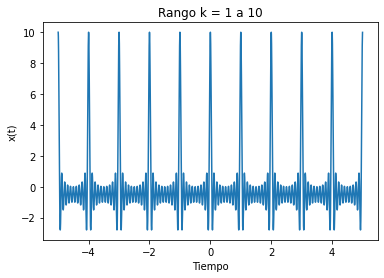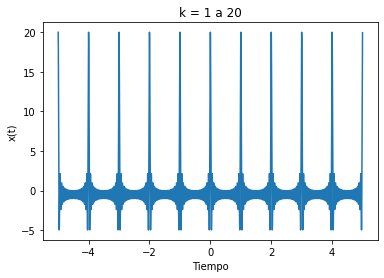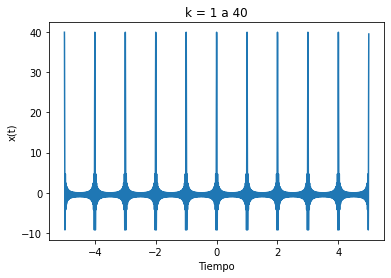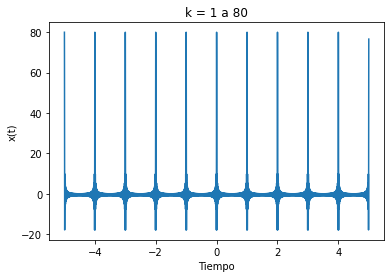

## **Problema 1: Reproducir Seccion 1.11 del Libro Lathi (versión de clase).**

**1.11-1 Funciones anónimas**

clear all; close all; clc;

f = @(t) exp(-t).*cos(2 * pi * t);
t = 0;
f(t)

ans = 1

f(0)

ans = 1

t = (-2:0.01:2);
f(t)

ans =     7.3891    7.3011    7.1856    7.0437    6.8763    6.6847    6.4701    6.2338    5.9773    5.7018    5.4090    5.1003    4.7773    4.4415    4.0946    3.7382    3.3739    3.0032    2.6278    2.2494    1.8694    1.4895    1.1111    0.7358    0.3650   -0.0000   -0.3577   -0.7070   -1.0464   -1.3750   -1.6915   -1.9950   -2.2845   -2.5592   -2.8181   -3.0606   -3.2860   -3.4938   -3.6835   -3.8547   -4.0071   -4.1404   -4.2544   -4.3492   -4.4246   -4.4809   -4.5180   -4.5364   -4.5362   -4.5178


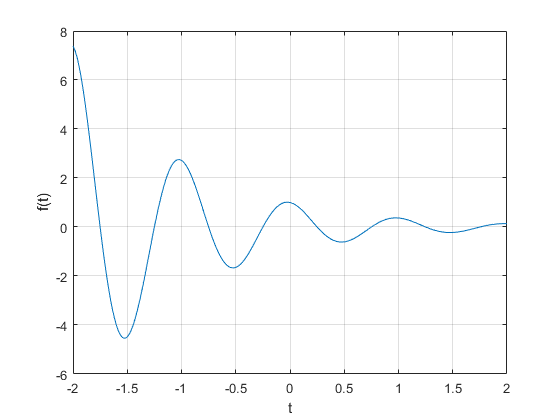

plot(t,f(t));
xlabel('t'); ylabel('f(t)'); grid;

**1.11-2 Operadores Relacionales y función del Escalón Unitario**

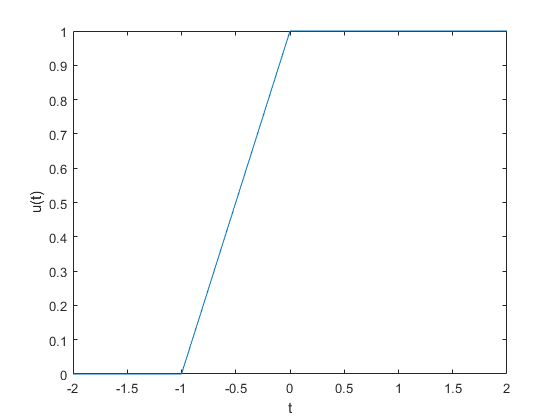

u = @(t) 1.0.*(t>=0);
t = (-2:2); plot(t, u(t));
xlabel('t'); ylabel('u(t)');

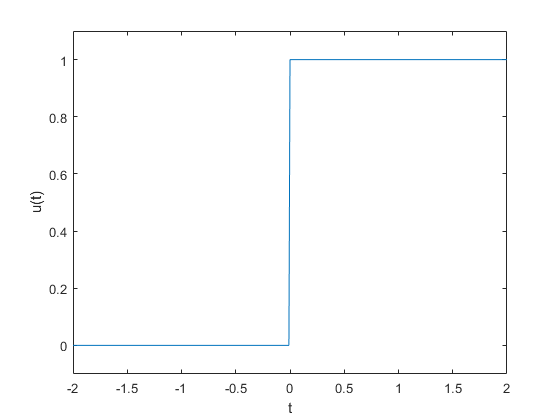

t = (-2: 0.01:2); plot(t, u(t));
xlabel('t'); ylabel('u(t)');
axis([-2 2 -0.1 1.1]);

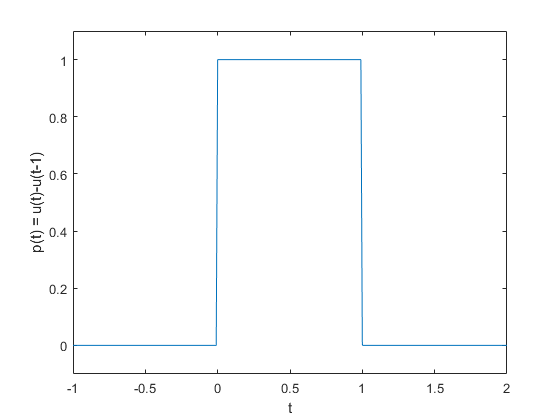

p = @(t) 1.0.*((t>=0)&(t<1));
t = (-1: 0.01: 2); plot(t, p(t));
xlabel('t'); ylabel('p(t) = u(t)-u(t-1)');
axis([-1 2 -0.1 1.1]);

**1.11-3 Visualización de Operaciones de variable independiente**

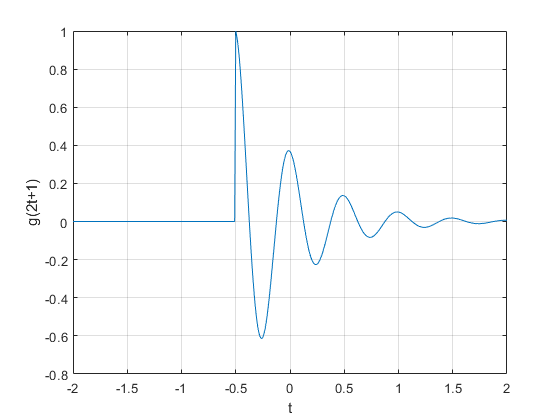

g = @(t) f(t).*u(t);

t = (-2: 0.01:2);
plot(t, g(2*t+1)); xlabel('t'); ylabel('g(2t+1)'); grid;

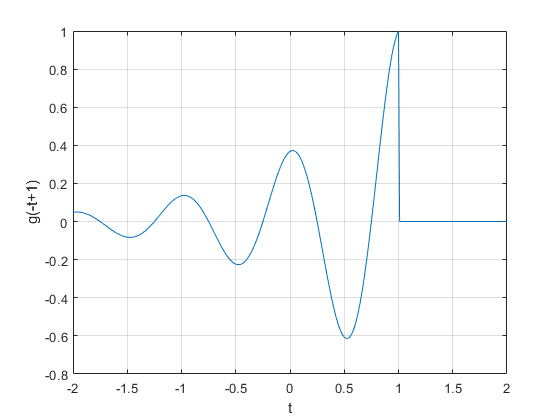

plot(t,g(-t+1)); xlabel('t'); ylabel('g(-t+1)'); grid;

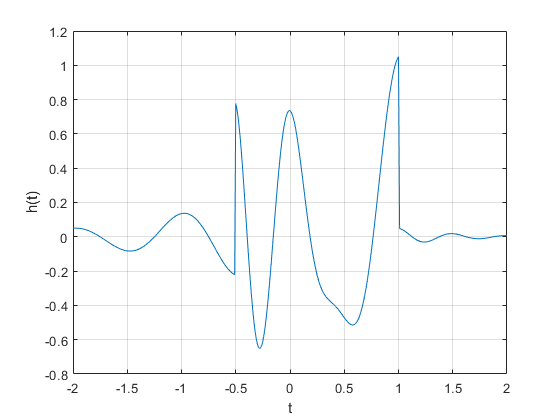


plot(t, g(2*t+1) + g(-t+1)); xlabel('t'); ylabel('h(t)'); grid;

**1.11-4 Integración numérica y estimación de la energía de una señal**

x = @(t) exp(-t).*((t>= 0) & (t<1));
t = (0:0.01:1);
E_x = sum(x(t).*x(t)*0.01)

E_x = 0.4367


x_squared = @(t) x(t).*x(t);

E_x = quad(x_squared, 0,1)

E_x = 0.4323


g_squared = @(t) g(t).*g(t);

t = (0:0.001: 100);
E_g = sum(g_squared(t)*0.001)

E_g = 0.2567

E_g = quad(g_squared, 0,100)

E_g = 0.2562

## **Problema 2: Problema 1.2-2 Lathi**

clear all; close all; clc;


**Señal x(t) ilustrada de la Fig. P1.2-2**

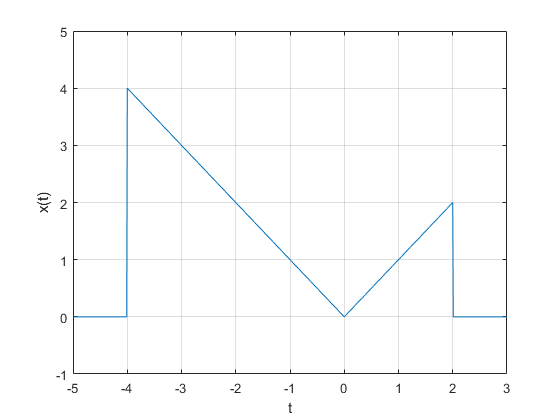

t = (-5: 0.01: 3);

f = @(t) abs(t).*((t>=-4)&(t<=2));

plot(t, f(t));
xlabel('t');
ylabel('x(t)');
axis([-5 3 -1 5]);
grid;

**a) x(t-4)**

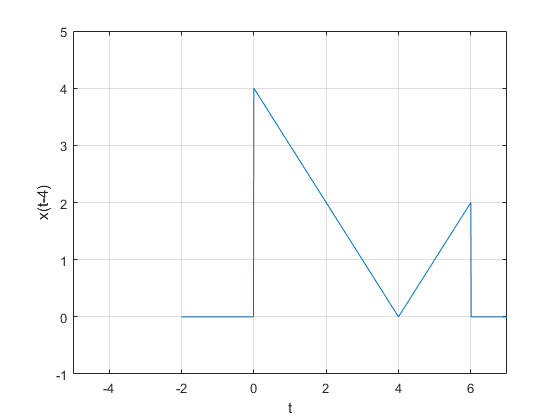

t = (-2: 0.01: 7);
f = @(t) abs(t-4).*((t>=0)&(t<=6));

plot(t, f(t));
xlabel('t');
ylabel('x(t-4)');
axis([-5 7 -1 5]);
grid;

**b) x(t/1.5)**

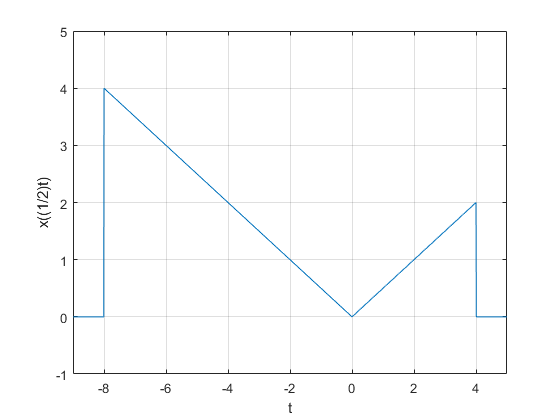

t = (-9: 0.01: 5);

f = @(t) abs(t).*((t>=-4)&(t<=2));

plot(t, f(0.5*t));
xlabel('t');
ylabel('x((1/2)t)');
axis([-9 5 -1 5]);
grid;

**c) x(-t)**

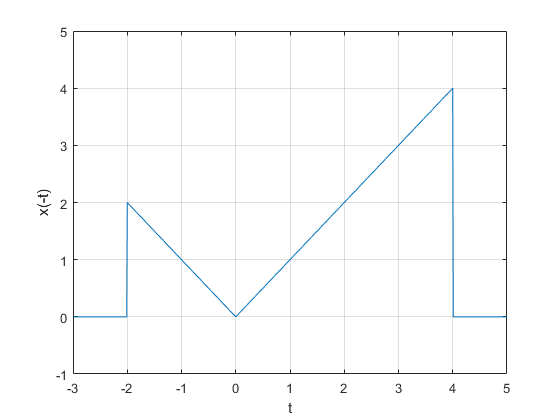

t = (-3: 0.01: 5);

f = @(t) abs(t).*((t>=-4)&(t<=2));

plot(t, f(-t));
xlabel('t');
ylabel('x(-t)');
axis([-3 5 -1 5]);
grid;

**d) x(2t-4)**

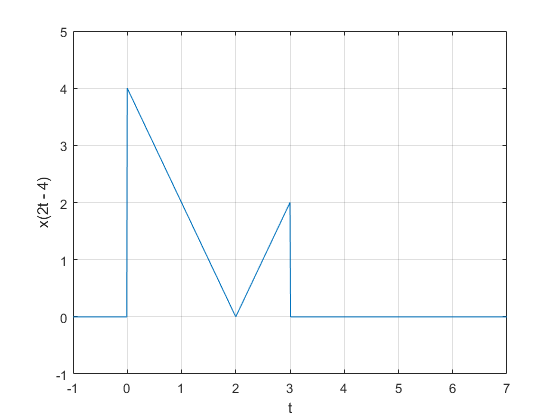

t = (-2: 0.01: 7);
f = @(t) abs(2*t - 4).*((t>=0)&(t<=3));

plot(t, f(t));
xlabel('t');
ylabel('x(2t - 4)');
axis([-1 7 -1 5]);
grid;

**e) x(2-t)**

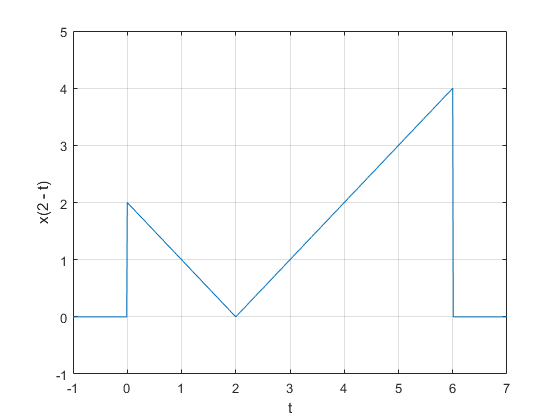

t = (-1: 0.01: 7);

f = @(t) abs(t).*((t>=-4)&(t<=2));

plot(t, f(2-t));
xlabel('t');
ylabel('x(2 - t)');
axis([-1 7 -1 5]);
grid;

## **Problema 3: Problema 1.11-1 Lathi**

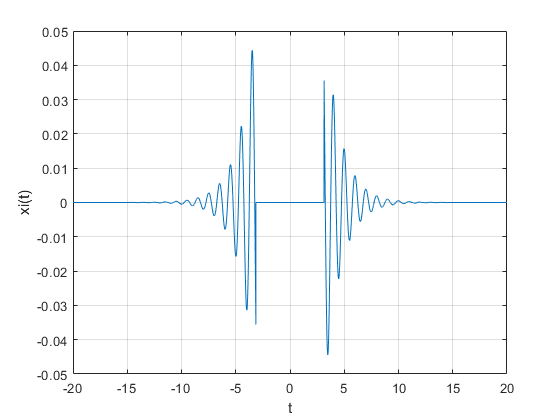

clear all; clc; close all;

u = @(t) 1.0*(t>=0);
x = @(t) 2.^(-t).*cos(2 * pi * t).*u(t-pi);

xi = @(t) (x(t) - x(-t))/2;

t = [-20: 0.001: 20];

plot(t, xi(t));
xlabel('t');
ylabel('xi(t)');
grid;

## **Problema 4: Construir la gráfica de **$x(t)=\sum_{k=1}^{10}\cos(2\pi kt)$

clear all; close all; clc;
syms t

**Rango k = 1 a 10**

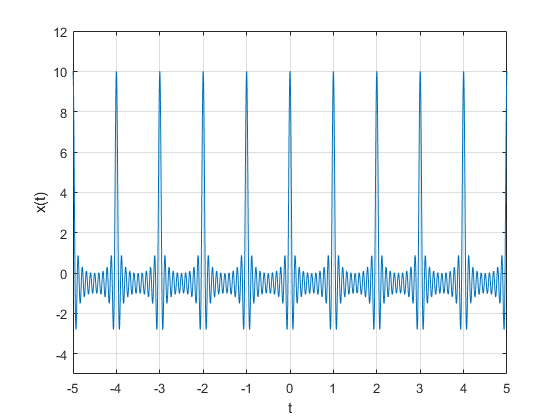

sf = 0;
for k = 1:10
    sf = sf + cos(k*pi*t*2);
end

fplot(sf);
xlabel('t');
ylabel('x(t)');
axis([-5 5 -5 12]);
grid;

**Rango k = 1 a 20**

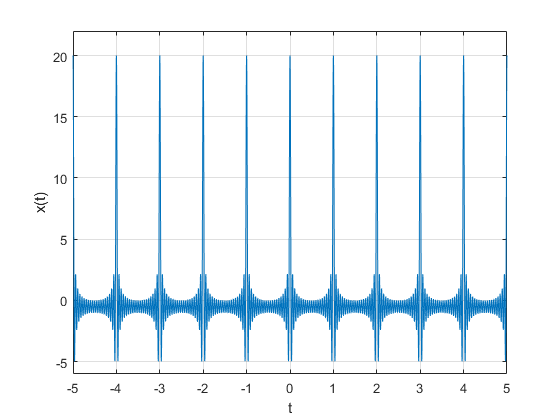

sf = 0;
for k = 1:20
    sf = sf + cos(k*pi*t*2);
end

fplot(sf);
xlabel('t');
ylabel('x(t)');
axis([-5 5 -6 22]);
grid;

**Rango k = 1 a 40**

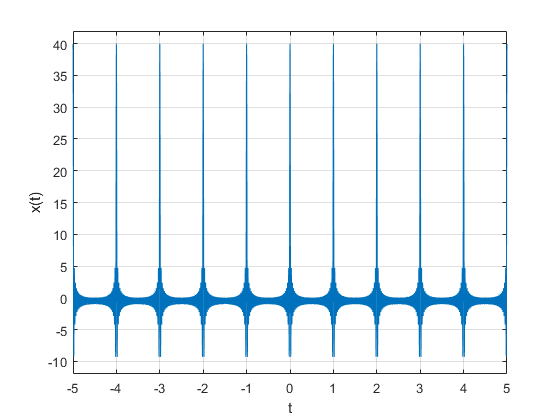

sf = 0;
for k = 1:40
    sf = sf + cos(k*pi*t*2);
end

fplot(sf);
xlabel('t');
ylabel('x(t)');
axis([-5 5 -12 42]);
grid;

**Rango k = 1 a 80**

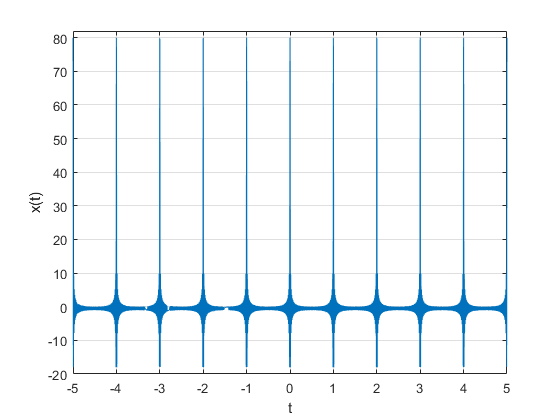

sf = 0;
for k = 1:80
    sf = sf + cos(k*pi*t*2);
end

fplot(sf);
xlabel('t');
ylabel('x(t)');
axis([-5 5 -20 82]);
grid;

## Problema 5: Problema 1.11-3 Lathi

clear all; clc; close all;


**a) Graficar Re{x(t)} contra Im{x(at)} para a = 0.5, 1 y 2 en el intervalo **$-10\le t\le 10$

t = [ -10: 0.001: 10];
u = @(t) 1.0.*(t>=0);
x = @(t) exp(t*(1+j*2*pi)).*u(-t);
y = @(t) real(2*x((-5-t)/2));

Para a = 0.5

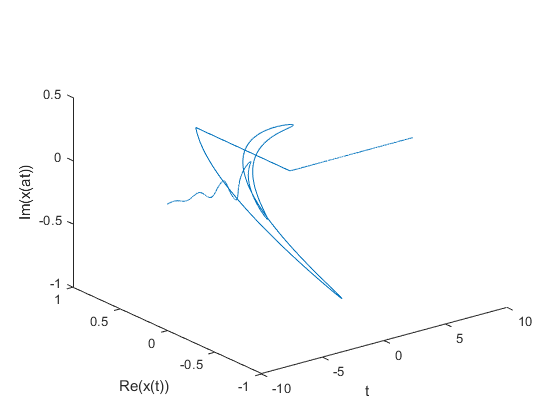

a = 0.5;

plot3(t, real(x(t)), imag(x(a*t)));

xlabel('t');
ylabel('Re(x(t))');
zlabel('Im(x(at))');

Para a = 1

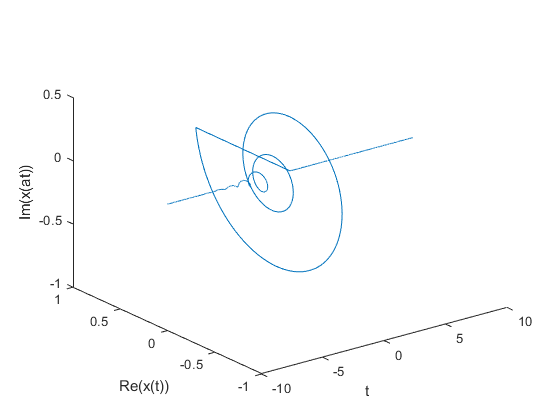

a = 1;

plot3(t, real(x(t)), imag(x(a*t)));

xlabel('t');
ylabel('Re(x(t))');
zlabel('Im(x(at))');

Para a = 2

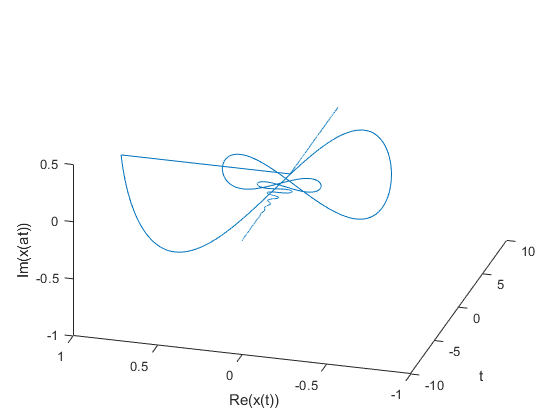

a = 2;

plot3(t, real(x(t)), imag(x(a*t)));

xlabel('t');
ylabel('Re(x(t))');
zlabel('Im(x(at))');

**b) Graficar y(t) en el intervalo **$-10\le t\le 10$

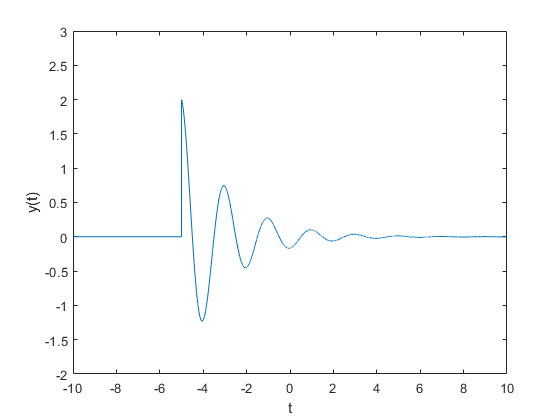

plot(t, y(t));

xlabel('t');
ylabel('y(t)');
axis([-10 10 -2 3]);

**c) Integracón numérica para calcular la energía de x(t)**

xeFun = @(t) abs(x(t)).^2;
E_x = integral(xeFun,-Inf, Inf)

E_x = 0.5000

**d) Integración numérica para calcular la energía de  y(t)**

yeFun = @(t) abs(y(t)).^2;
E_y = integral(yeFun, -Inf, inf)

E_y = NaN

**Inciso extra: e) Graficar x(t) sobre el intervalo de **$-10\le t\le 10$

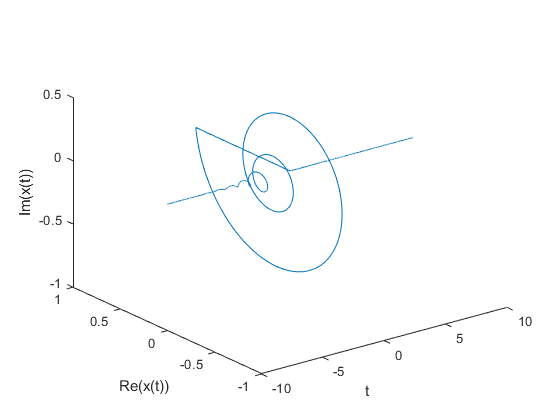

t = [ -10: 0.001: 10];
plot3(t, real(x(t)), imag(x(t)));

xlabel('t');
ylabel('Re(x(t))');
zlabel('Im(x(t))');

## Problema 6 Construcción de la App

**Se adjunta la imagen  de la interfaz de la aplicación y también el enlace para descargar el **[ archivo .mlapp](https://github.com/DemondAngel/SySPractica2/blob/main/PRACTICA2.mlapp)** .**

**Enlace del **[código](https://drive.google.com/file/d/1K5_zRndBV_JYnFMJnr31azNiMN-x1XGE/view?usp=sharing)** en Google Drive**